# 4.8 Observer

Full-order

load Linear_Param.mat
load poles.mat
format shortE
B1 = B(:,1)

B1 =             0
   2.0576e+01
            0
  -9.0028e+01


K = acker(A,B1,poles)

K =   -2.9155e+01  -4.9970e+01  -8.1847e+01  -1.3640e+01


C = [1 0 0 0;0 0 1 0]

C =      1     0     0     0
     0     0     1     0


factor = 4;
speed = max(abs(poles(2:4)));
contObserverPoles(1) = poles(1);
contObserverPoles(2) = -2*factor*speed; % Place pole to not disturb dominant poles
omegan = factor*speed;
zeta = 0.99;
contObserverPoles(3:4) =    [omegan*(-zeta+1i*sqrt(1-zeta^2));
                             omegan*(-zeta-1i*sqrt(1-zeta^2))];
L = (place(A',C',contObserverPoles))'

L =    3.2003e+01  -4.1389e+01
  -3.8725e+03   1.7274e+04
  -4.8252e+01   2.3864e+02
   1.6798e+04  -7.4441e+04


poles

poles =   -6.6476e+02 + 0.0000e+00i
  -5.0809e+00 + 0.0000e+00i
  -2.4802e+00 + 3.5205e-01i
  -2.4802e+00 - 3.5205e-01i


contObserverPoles

contObserverPoles =   -6.6476e+02 + 0.0000e+00i  -4.0647e+01 + 0.0000e+00i  -2.0120e+01 + 2.8670e+00i  -2.0120e+01 - 2.8670e+00i


observerPoles = eig(A-L*C)

observerPoles =   -6.6476e+02 + 0.0000e+00i
  -4.0647e+01 + 0.0000e+00i
  -2.0120e+01 + 2.8670e+00i
  -2.0120e+01 - 2.8670e+00i


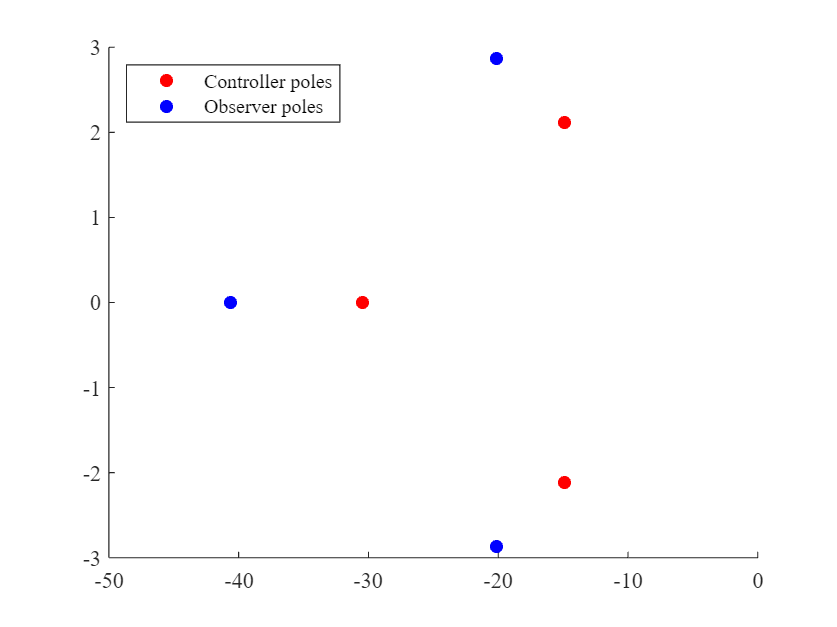

scatter(real(6*poles),imag(6*poles),"filled","red")
hold on

scatter(real(observerPoles),imag(observerPoles),"filled","blue")
legend("Controller poles","Observer poles","location","northwest")
xlim([-50,0])
hold off

Reduced order

T = inv([C;0 1 0 0; 0 0 0 1])

T =      1     0     0     0
     0     0     1     0
     0     1     0     0
     0     0     0     1


% T = eye(4)
An = inv(T)*A*T   %New A-matrix

An =             0            0   1.0000e+00            0
            0            0            0   1.0000e+00
            0  -6.0991e+00  -4.3503e+02   9.1357e+00
            0   6.2019e+01   1.9034e+03  -3.9972e+01


Bn = inv(T)*B(:,1)     %New B-matrix

Bn =             0
            0
   2.0576e+01
  -9.0028e+01


Cbacc = C(1,:)*T  %Accurate

Cbacc =      1     0     0     0


Cbnacc = C(2,:)*T %Not accurate

Cbnacc =      0     1     0     0



Ayy = An(1,1); %Zero
Ayx = An(1,2:4)  %Noisy/unobserved states

Ayx =      0     1     0


Axy = An(2:4,1); % Zero
Axx = An(2:4,2:4) %Noisy/unobserved states

Axx =             0            0   1.0000e+00
  -6.0991e+00  -4.3503e+02   9.1357e+00
   6.2019e+01   1.9034e+03  -3.9972e+01



By = Bn(1);
Bx = Bn(2:4)

Bx =             0
   2.0576e+01
  -9.0028e+01



Cy = Cbnacc(1);
Cx = Cbnacc(2:4)

Cx =      1     0     0



AA = Axx

AA =             0            0   1.0000e+00
  -6.0991e+00  -4.3503e+02   9.1357e+00
   6.2019e+01   1.9034e+03  -3.9972e+01


CC = [Ayx
      Cx]

CC =      0     1     0
     1     0     0


L = ( place( AA', CC', contObserverPoles(2:4) ) )'

L =   -4.3675e+00   4.0169e+01
  -4.3429e+02  -1.0467e+01
   1.9470e+03   6.6783e+01


vpa(sym(L),5)

$$ans = \left(\begin{array}{cc} -4.3675 & 40.169\\ -434.29 & -10.467\\ 1947.0 & 66.783 \end{array}\right)$$

Lacc = L(:,1)

Lacc =   -4.3675e+00
  -4.3429e+02
   1.9470e+03


Lnacc = L(:,2)

Lnacc =    4.0169e+01
  -1.0467e+01
   6.6783e+01



poles(2:4)

ans =   -5.0809e+00 + 0.0000e+00i
  -2.4802e+00 + 3.5205e-01i
  -2.4802e+00 - 3.5205e-01i


observerPoles = eig(AA-L*CC)

observerPoles =   -4.0647e+01 + 0.0000e+00i
  -2.0120e+01 + 2.8670e+00i
  -2.0120e+01 - 2.8670e+00i


Determining gains of reduced order estimator. Simply plugging in equation from lab instruction gives:

M1 = Axx-Lacc*Ayx-Lnacc*Cx

M1 =   -4.0169e+01   4.3675e+00   1.0000e+00
   4.3675e+00  -7.4683e-01   9.1357e+00
  -4.7633e+00  -4.3516e+01  -3.9972e+01


vpa(sym(M1),5)

$$ans = \left(\begin{array}{ccc} -40.169 & 4.3675 & 1.0\\ 4.3675 & -0.74683 & 9.1357\\ -4.7633 & -43.516 & -39.972 \end{array}\right)$$

M2 = Bx-Lacc*By

M2 =             0
   2.0576e+01
  -9.0028e+01


vpa(sym(M2),5)

$$ans = \left(\begin{array}{c} 0\\ 20.576\\ -90.028 \end{array}\right)$$

M3 = Axy-Lacc*Ayy-Lnacc*Cy

M3 =      0
     0
     0


vpa(sym(M3),5)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

M4 = Lnacc

M4 =    4.0169e+01
  -1.0467e+01
   6.6783e+01


vpa(sym(M4),5)

$$ans = \left(\begin{array}{c} 40.169\\ -10.467\\ 66.783 \end{array}\right)$$

M5 = Lacc

M5 =   -4.3675e+00
  -4.3429e+02
   1.9470e+03


vpa(sym(M5),5)

$$ans = \left(\begin{array}{c} -4.3675\\ -434.29\\ 1947.0 \end{array}\right)$$

M6 = T(:,1)

M6 =      1
     0
     0
     0


vpa(sym(M6),5)

$$ans = \left(\begin{array}{c} 1.0\\ 0\\ 0\\ 0 \end{array}\right)$$

M7 = T(:,2:4)

M7 =      0     0     0
     0     1     0
     1     0     0
     0     0     1


vpa(sym(M7),5)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 1.0 & 0\\ 1.0 & 0 & 0\\ 0 & 0 & 1.0 \end{array}\right)$$